%Code example of NCP processing for Station720;
%raw excel file used: 
% Station720.xlsx (note:modified datetime column in Excel)
% EST_sun.xlsx (modified from NOAA website: https://gml.noaa.gov/grad/solcalc/)

%importe data: from Station720.xlsx to Station720.mat
Station720 = readtable('Station720.xlsx');
x=table2array(Station720(:,1));
xx=datetime(x, 'InputFormat', 'dd-MMM-yyyy HH:mm:ss') - hours(5);
% xx=datetime(x,'convertfrom','excel');
ST720_time=datenum(xx);
ST720_time(:,2:7)=datevec(xx);

%saved two files for future use: ST720_time.mat and ST720_data.mat

Station720 = readmatrix('Station720.xlsx');
% ST720_DO = Station720(:,5);
ST720_T = Station720(:,2);
ST720_S = Station720(:,3);
ST720_DO=ST720_data(:,4); % unit: mg/L 
% ST720_T=ST720_data(:,2);  %unit: deg C
% ST720_S=ST720_data(:,3);  %unit: psu


%calculate O2 saturation using function o2satv2a.m

ST720_DOsat1=o2sat(ST720_S,ST720_T); %unit: mg/L

rho =           1.02293491942388
          1.02268224373742
          1.02243162369851
          1.02249339088864
          1.02256319489122
          1.02309037176001
          1.02309637452088
          1.02310900483825
          1.02310530381322
          1.02308605254998



%transfer units for DOsat1 to mg/L:  ./22.4 .*32  
% ST720_DOsat=ST720_DOsat1 ./22.4 .* 32; %unit: mg/L
ST720_DOsat=o2sat(ST720_S,ST720_T);

rho =           1.02293491942388
          1.02268224373742
          1.02243162369851
          1.02249339088864
          1.02256319489122
          1.02309037176001
          1.02309637452088
          1.02310900483825
          1.02310530381322
          1.02308605254998


%use method described in Oviatt et al. 2017 ( citing Kremer et al. 2003)
% Air-sea flux (J)= K .* SD, where K is permiability coefficient (g O2 m-2 h-1 atm-1) and SD is
% saturation deficit (SD=0.209.* (Cs-C0)./Cs), where C0 is measured O2 conc. and Cs is sat conc. 

%%% PS: if transfer to piston velosity, KL=K.*0.209 (atm) ./ S (g O2 m-3)

% coeffecient: assume 5m/s wind at 10m above surface
K=0.55 .* exp(0.15*5);  %equation for combined in kremer et al. 2003
%unit: g O2 m-2 h-1 atm-1

%calculate SD
%SD is saturation deficit (SD=0.209.* (Cs-C0)./Cs)
ST720_SD=0.209 .* (ST720_DOsat-ST720_DO)./ST720_DOsat; %unitless


%calculate D (same as J in Kremer 2003)-- air-sea gas exchange flux
% from seawater to air: negative;
% from air to seawater: positive
ST720_D_rate=K.* ST720_SD; %unit: same as K, g O2 m-2 h-1 atm-1


%calculate dC/dt for each row
for i=1:length(ST720_time)-1
    ST720_dif(i+1,1)=ST720_DO(i+1)-ST720_DO(i);
end


%ST720_dif unit: mg O2/L or g O2 /m-3

%sunrise and sunset file: "EST_sun.xlsx" imported as "ESTsun.mat"
%removed daylight saving time, all time in EST, comparable with O2 data
%etc.

%identify day/night
%sunrise and sunset data in "ESTsun.mat"
%comlumn 1-3 are year, month, day;
%column 4-6 are sunrise hour, minute, second;
%column 7-9 are sunset hour, minute, second;
%column 10 is sunrise datenum;
%column 11 is sunset datenum;

%For each day, identified as start from sunrise and end at next day sunrise

%first day datenum:738522

ESTsun(:,10)=datenum(ESTsun(:,1:6));
ESTsun(:,11)=datenum(ESTsun(:,[1,2,3,7,8,9]));
%column 10 is sunrise datenum;
%column 11 is sunset datenum;

sunrise=ESTsun(:,10);
sunset=ESTsun(:,11);

date(1:729,1)=(738522:1:739250);%set date numbers for sunset/sunrise days
date(:,2:7)=datevec(date(:,1));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

test_time=ST720_time(:,1);
test_D_rate=ST720_D_rate;
test_DO=ST720_DO;
test_dif=ST720_dif;

% %%this part is not used after the code is modified, please ignore

% for i=1:length(test_time)-1
% testtimedif(i+1,1)=test_time(i+1)-test_time(i);
% end
% 
% aa=[];
% for i=1:length(test_time)-1
%     aa=find(testtimedif>0.05);
% end
% % output 'aa' shows the row numbers where time point gaps are more than 1h interval
% % (likely a discontinuous time point)
% 
% test_dif(aa)=0; %remove non-continuous time points


%test sunset to sunrise; try to get respiration for each day
%e.g. May 25th sunset to May 26th sunrise, sum in row 25

test_night_dif=[]; %night period DO difference
test_night_duration=[]; %night period available data time-duration
test_night_D=[];%night period air-sea flux
test_night_full=[];%time between sunset and next day sunrise
a=1;

for i=1:length(sunrise)-1
    test_night_full(a,1)=24.* (sunrise(i+1)-sunset(i));%the length of the entire night, unit: h
    
    tt=find(test_time>sunset(i) & test_time<=sunrise(i+1));
    
   if isempty(tt)
    test_night_dif(a,1)=nan;
    test_night_duration(a,1)=nan;
    test_night_D(a,1)=nan;
    gap_night_sum(a,1)=nan;
    a=a+1;
   else

   test_night_dif(a,1)=test_DO(max(tt))-test_DO(min(tt)); %night time DO change, unit: mg O2/L or g O2 /m-3
   test_night_duration(a,1)= (test_time(max(tt))-test_time(min(tt))).*24; % night-time duration, unit:h

        for n=1:length(tt)-1
        gap_night(n,1)=(test_time(tt(n+1))-test_time(tt(n))).*24;%time length between two time points, unit:h
        gap_night_D(n,1)=test_D_rate(tt(n)).*gap_night(n);%air-sea flux between two time points: rate (ST720_D_rate) .* time length,
        % gap_D unit: g O2 m-2 atm-1
        test_night_D(a,1)=sum(gap_night_D(1:n));%unit: g O2 m-2 atm-1
        gap_night_sum(a,1)=sum(gap_night);
        end

   a=a+1;
   clear gap_night gap_night_D
   end
   clear tt
end
%get test_night_dif as night-time DO difference

%data clean-up: remove days when gap_sum<5h (have less than 5h night data)
mm=find(test_night_duration<5);
test_night_duration(mm)=nan;
test_night_D(mm)=nan;
test_night_dif(mm)=nan;

%extrapolate air-sea flux to the length of entire night
test_night_fullD=test_night_D ./ test_night_duration .* test_night_full;  %unit: g O2 m-2 atm-1
test_night_fulldif=test_night_dif ./ test_night_duration .* test_night_full; %unit: g O2 /m-3

%calculate night-time respiration
%P-R=dC/dt-D
% at night, R=D-dC/dt

test_night_fullR=test_night_fullD - (7.* test_night_fulldif); %unit: g O2 m-2; assumed 7m water depth here.
test_night_fullR_rate= test_night_fullR ./ test_night_full; %unit: g O2 m-2 h-1

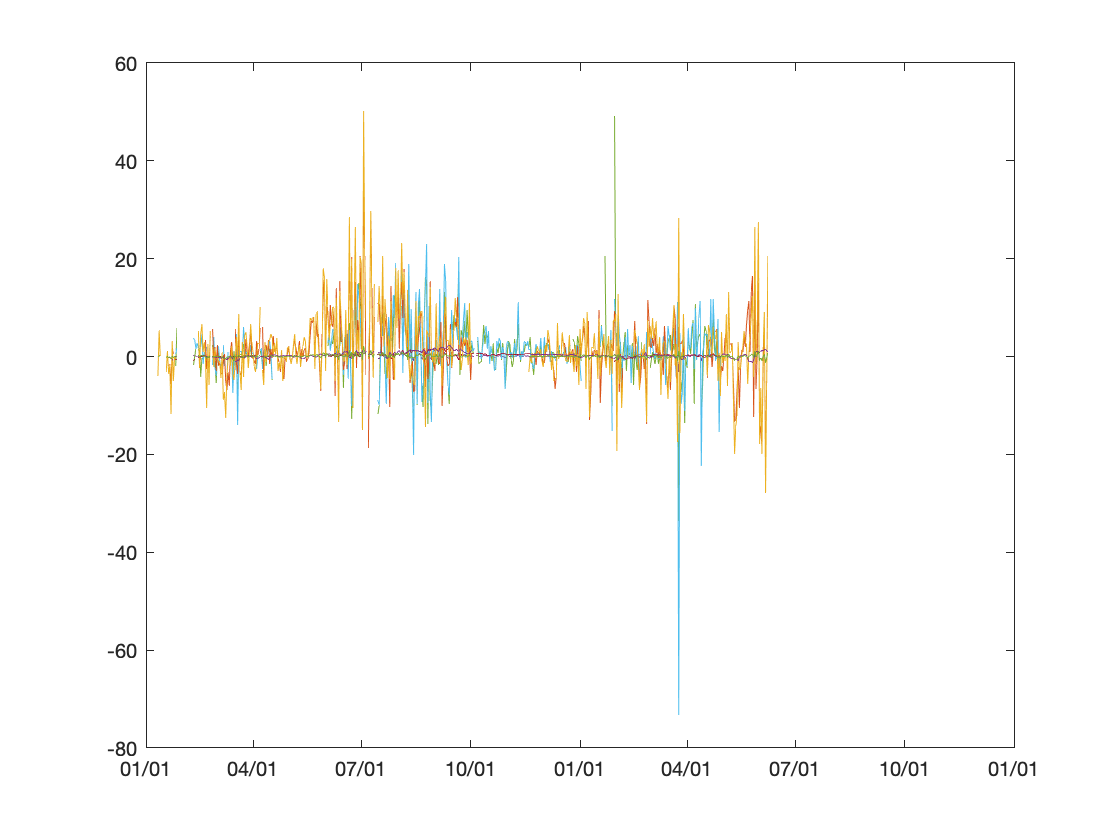

plot(date(:,1),test_night_fullR_rate);
datetick('x',6);


%Note: for some days, R is calculated as negative values due to a higher DO
%at sunrise than sunset. 
% Negative R values can be potentially removed.


%try to get day time production
%P-R=dC/dt-D
%P=R+dc/dt-D
test_day_dif=[];%day time DO difference
test_day_duration=[];%day period available data time-duration
test_day_D=[];%day time air-sea flux
test_day_full=[];%time length from sunrise to sunset
a=1;

for i=1:length(sunrise)-1
    test_day_full(a,1)=24.* (sunset(i)-sunrise(i));%the length of the entire day, unit: h
    
    tt=find(test_time<=sunset(i) & test_time>sunrise(i));
    
if isempty(tt)
    test_day_dif(a,1)=nan;
    test_day_duration(a,1)=nan;
    test_day_D(a,1)=nan;
    gap_day_sum(a,1)=nan;
    a=a+1;
else

test_day_dif(a,1)=test_DO(max(tt))-test_DO(min(tt)); %day time DO change, unit: mg O2/L or g O2 /m-3
test_day_duration(a,1)= (test_time(max(tt))-test_time(min(tt))).*24; % day-time data duration, unit:h

for n=1:length(tt)-1
    gap_day(n,1)=(test_time(tt(n+1))-test_time(tt(n))).*24;%time length between two time points, unit:h
    gap_day_D(n,1)=test_D_rate(tt(n)).*gap_day(n);%air-sea flux between two time points: rate (ST720_D_rate) .* time length,
    % gap_day_D unit: g O2 m-2 atm-1
    test_day_D(a,1)=sum(gap_day_D(1:n));%unit: g O2 m-2 atm-1
    gap_day_sum(a,1)=sum(gap_day);
end

a=a+1;
clear gap_day gap_day_D 
end
clear tt
end

%data clean-up: remove test_day_R on days when gap_sum<5h
mm=find(test_day_duration<5);
test_day_duration(mm)=nan;
test_day_D(mm)=nan;
test_day_dif(mm)=nan;

%corrected air-sea flux to the length of entire day
test_day_fullD=test_day_D ./ test_day_duration .* test_day_full;  %unit: g O2 m-2 atm-1
test_day_fulldif=test_day_dif ./ test_day_duration .* test_day_full; %unit: g O2 /m-3

%calculate production using day time
% P=dc/dt+R-D
test_fullP=(test_day_fulldif .*7) + (test_night_fullR_rate .*test_day_duration) - test_day_fullD;

%whole day respiration
test_fullR=test_night_fullR_rate .*24;%unit: g O2 m-2

%whole day air-sea flux
test_fullD=test_night_fullD+test_day_fullD;%unit: g O2 m-2 

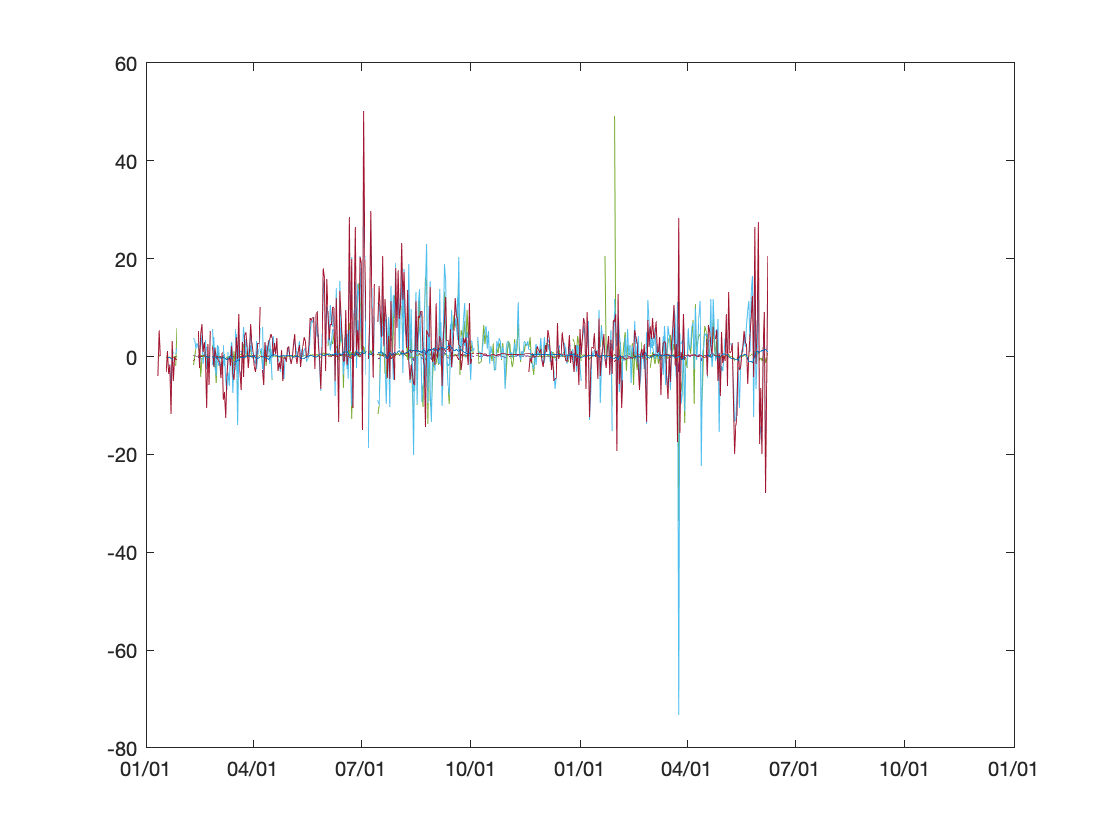

plot(date(:,1),test_fullP);
datetick('x',6);
hold on;
plot(date(:,1),test_fullR);
plot(date(:,1),test_fullD);

%what we need here is NCP or NEM, which is NEM=P-R=dC/dt-D
test_NEM=test_fullP-test_fullR;

test_NEM2=(test_day_fulldif .*7)+(test_night_fulldif .*7)-test_fullD;

%unit: g O2 m-2


NEM_C=test_NEM./32./138.*106; %in carbon units, unit: mol C m-2

figure(2)
plot(date(:,1),NEM_C);